# DYSKR

A = [-1 0; 0, -2];
x0 = [1; 1];

syms t_s;
syms h_s
disp("Analityc solution")

Analityc solution


y = expm(A.*t_s)*x0

$$y = \left(\begin{array}{c} {\mathrm{e}}^{-t_{s}}\\ {\mathrm{e}}^{-2\,t_{s}} \end{array}\right)$$

A_plus_s = expm(A.*h_s)

$$A\_plus\_s = \left(\begin{array}{cc} {\mathrm{e}}^{-h_{s}} & 0\\ 0 & {\mathrm{e}}^{-2\,h_{s}} \end{array}\right)$$


euler_forw = @(A, h, x) (eye(2, 2) + h*A)*x; 
euler_back = @(A, h, x) ((eye(2, 2) - h*A)^-1)*x; 
NewtonColes = @(A, h, x) (eye(2, 2) + 0.5*h*A)*((eye(2, 2) - 0.5*h*A)^-1)*x

NewtonColes = function_handle with value:
    @(A,h,x)(eye(2,2)+0.5*h*A)*((eye(2,2)-0.5*h*A)^-1)*x


cont2discr = @(A, h) (expm(A.*h))

cont2discr = function_handle with value:
    @(A,h)(expm(A.*h))



lmdb = eig(A_plus)

lmdb =     -2
    -1


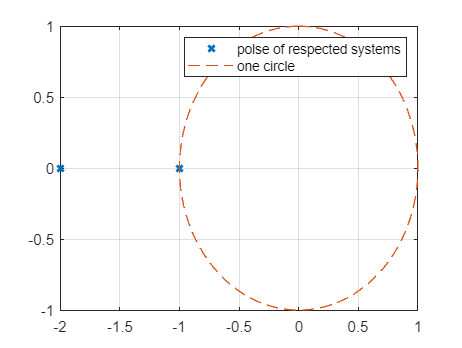


figure
plot(real(lmdb), imag(lmdb), 'x', LineWidth=2)
hold on
w = linspace(0,2*pi,100);
plot(sin(w),cos(w), "--");
legend(["polse of respected systems", "one circle"])
grid on;